## Вычисление АЧХ интегрирующего звена

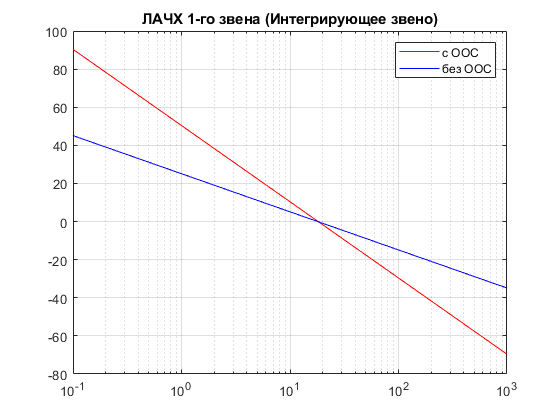

clear all;
w = logspace(-1, 3);
W1 = 20 * log10(18) - 20 * log10(w);
W1ooc=20*log10(1) - 20*log10((w.^2)*(0.055^2));
semilogx(w, W1ooc, "red", w, W1, "blue"); title('ЛАЧХ 1-го звена (Интегрирующее звено)'); legend('с ООС', 'без ООС'); grid on;

## Вычисление ФЧХ интегрирующего звена

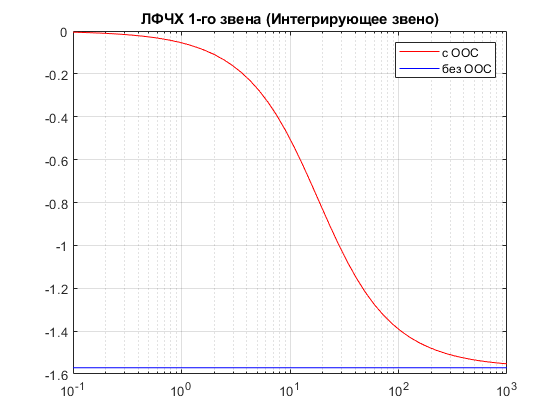

w = logspace(-1, 3);
fi1 = -(pi/2)*w.^0;
fi1ooc = -atan(0.055*w);
semilogx(w, fi1ooc, "red", w, fi1, "blue"); title('ЛФЧХ 1-го звена (Интегрирующее звено)'); legend('с ООС', 'без ООС'); grid on;

## Расчет h(t) и l(t) интегрирующего звена

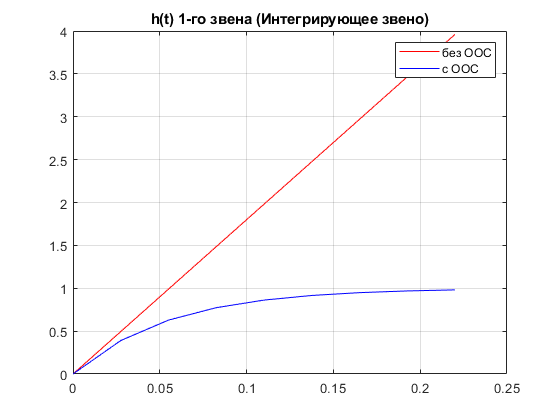

T = 0.055;
t = 0 : T/2 : 4*T;
h1 = 18 * t;
l1 = 18 * (t.^2) / 2;
h1ooc = 1 - exp(-18 * t);
l1ooc = t - (1 - exp(-18*t))/18;
plot(t, h1, "red", t, h1ooc, "blue"); title('h(t) 1-го звена (Интегрирующее звено)'); legend('без ООС', 'с ООС'); grid on;

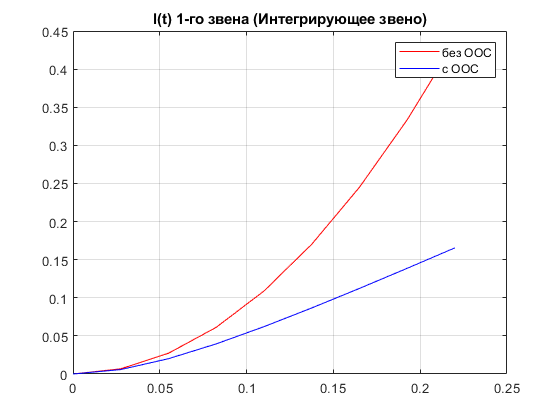

plot(t, l1, "red", t, l1ooc, "blue"); title('l(t) 1-го звена (Интегрирующее звено)'); legend('без ООС', 'с ООС'); grid on;

## Вычисление АЧХ инерционного звена

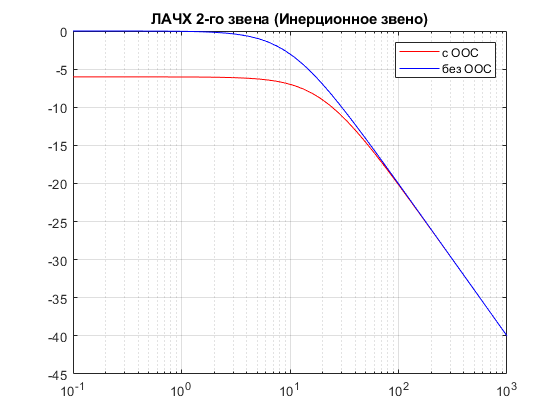

w = logspace(-1, 3);
% W2ooc = 20*log10(0.5 ./ sqrt(1 + (0.05.^2)*(w.^2)));
W2 = 20*log10(1 ./ sqrt(1 + (0.1.^2)*(w.^2)));
% semilogx(w, W2ooc, "red", w, W2, "blue"); title('ЛАЧХ 2-го звена (Инерционное звено)'); legend('с ООС', 'без ООС'); grid on;

semilogx(w, W2, "blue"); title('ЛАЧХ'); legend('без ООС'); grid on;

## Вычисление ФЧХ инерционного звена

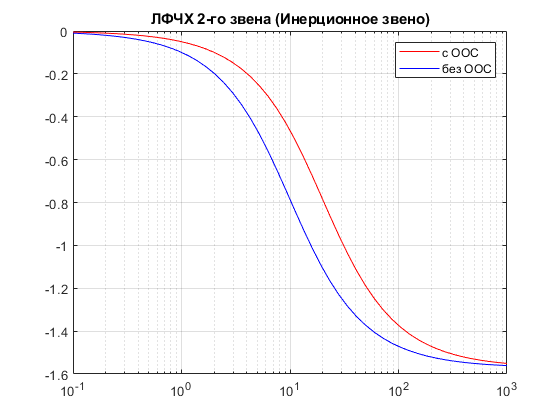

w = logspace(-1, 3);
fi2ooc = -atan(0.05*w);
fi2 = -atan(0.1*w);
semilogx(w, fi2ooc, "red", w, fi2, "blue"); title('ЛФЧХ 2-го звена (Инерционное звено)'); legend('с ООС', 'без ООС'); grid on;

## Расчет h(t) и l(t) инерционного звена

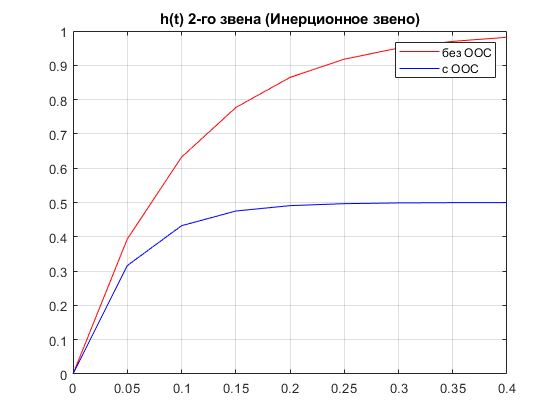

T = 0.1;
t = 0 : T/2 : 4*T;
h2 = 1 - exp(-10*t);
l2 = t - (1 - exp(-10*t))/10;
h2ooc = 0.5 * (1 - exp(-20 * t));
l2ooc = 0.5 * (t - (1 - exp(-20*t))/20);
plot(t, h2, "red", t, h2ooc, "blue"); title('h(t) 2-го звена (Инерционное звено)'); legend('без ООС', 'с ООС'); grid on;

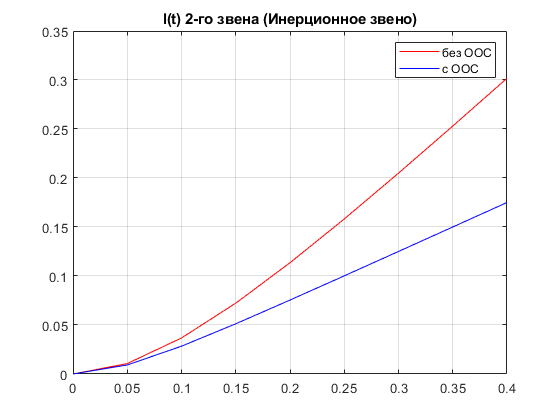

plot(t, l2, "red", t, l2ooc, "blue"); title('l(t) 2-го звена (Инерционное звено)'); legend('без ООС', 'с ООС'); grid on;

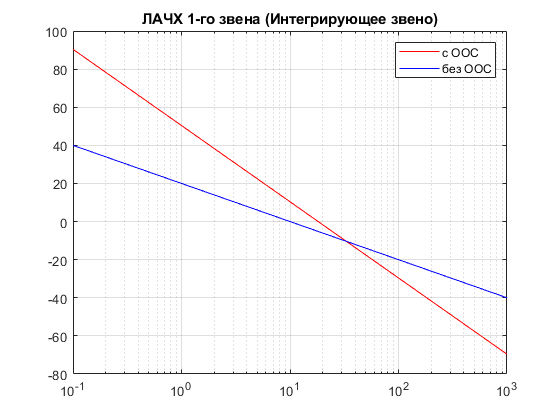


W1 = 20 * log10(10) - 20 * log10(w);
semilogx(w, W1ooc, "red", w, W1, "blue"); title('ЛАЧХ 1-го звена (Интегрирующее звено)'); legend('с ООС', 'без ООС'); grid on;

## 7-ой номер ФАЗА

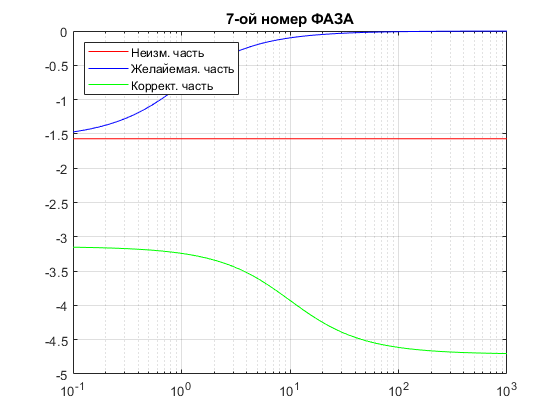

clear all;
w = logspace(-1, 3);
% T1 = 0.1;
% T2 = 0.398;
% T3 = 0.043;
% W1 = (-pi/2) + (-atan(T1.*w));
% W2 = (-pi) + (-atan(T3.*w)) + (atan(T2.*w));
% W3 = (-pi/2) + (-atan(T3.*w)) + (atan(T2.*w)) + (atan(T1.*w));
T1 = 0.3;
T2 = 1;
T3 = 0.1;
W1 = (-pi/2)*w.^0;
W2 = (atan(1.*w)) + (-pi/2);
W3 = (-pi) + (-atan(0.1.*w));

semilogx(w, W1, "red", w, W2, "blue", w, W3, "green"); title('7-ой номер ФАЗА'); legend({'Неизм. часть', 'Желайемая. часть', 'Коррект. часть'},'Location','northwest','NumColumns', 1); grid on;

## 7-ой пункт Расчет Дисперсии

a0 = 0.02;
a1 = 1;
a2 = 3.75;
a3 = 7.5;
b0 = 0.25;
b1 = 1;
b2 = 1;
S = 0.05;

J3 = ((-a2*b0) + (a0*b1) + (-(a0*a1*b2)/a3)) / (2*a0*(a0*a3 - a1*a2))

J3 = 6.3900

G = S * J3 * 15^2

G = 71.8880